MECE6397: Learning-Based Control

# Homework 3: Model Reference Adaptive Systems

Instructor: Marzia Cescon

The **model reference adaptive system** (MRAS) is an example of adaptive scheme in which the specifications of performance are expressed in terms of a reference model, which gives the desired response to a command signal. Due to this property, MRAS may be regarded as an adaptive servo system. The block diagram is illustrated in Figure 1. The controller can be thought of as having two loops. The inner loop is an ordinary feedback loop consisting in the process and a controller. The outer loop is another feedback loop which adjusts the controller parameters so that the error computed as the difference between the output of the system and the output of the reference model is small. The key problem with MRAS is to determine the adjustment mechanism such that a stable system which brings the error to zero is obtained.

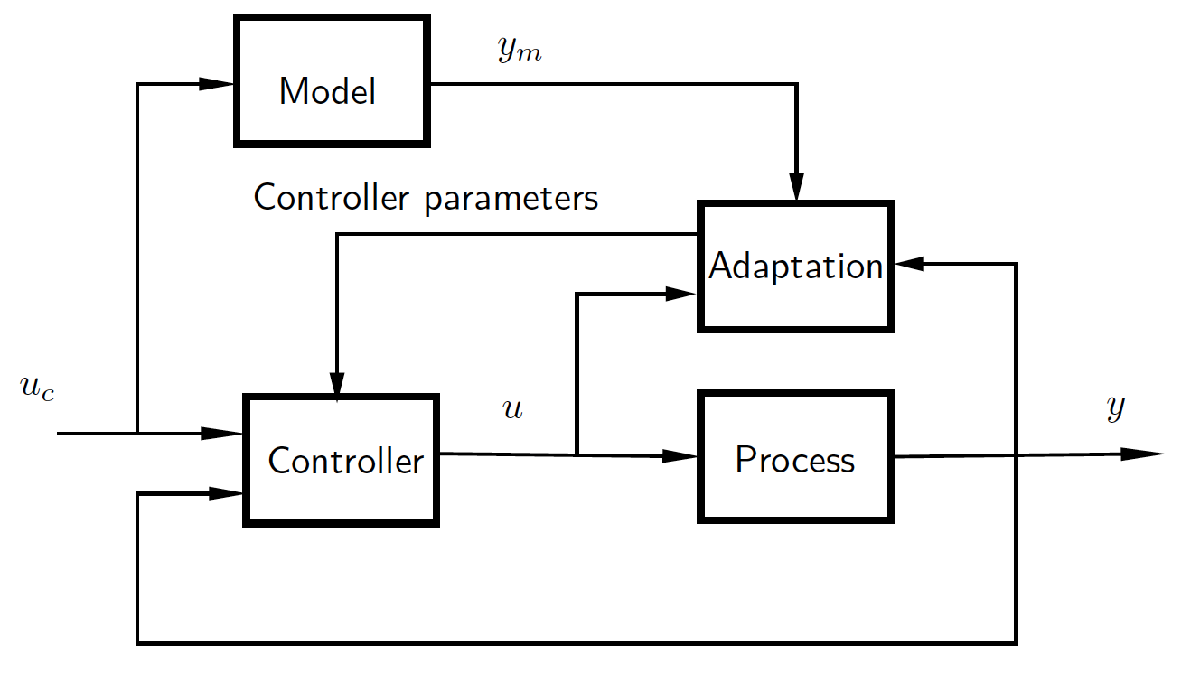

Figure 1. Block diagram of a model reference adaptive system.

 This homework is a simulation exercise with the goal of providing a good introduction to MRAS. The examples are drawn from the book: "Adaptive Control", by K.J. Åström and B. Wittenmark. Two ways to obtain mechanisms for the parameters adjustment are studied: the first one uses a gradient-based method, while the second one applies Lyapunov stability theory.

## 1. Adaptation of a feed-forward gain

We first consider the problem of adjusting a feedforward gain. Let us define the differential operator $p=\frac{d}{\textrm{dt}}$. We assume that the process is a linear stable SISO process, with input-output relationship $y\left(t\right)=G\left(p\right)u\left(t\right)$, with  $G\left(p\right)=\frac{k}{p+1}\;,\;$for some unknown parameter $k>0$, and that the reference model is given by the expression $y_m =G_m \left(p\right)u_c \left(t\right)$, with${\;G}_m \left(p\right)=\frac{k_0 }{p+1}$, where $k_0 >0$ is a known constant. We wish to construct a control law $u\left(t\right)$ for the process, which makes its output $y\left(t\right)$ behave as the output of the reference model $y_m \left(t\right)$ when controlled by the command signal $u_c \left(t\right)$. If such a control law can be established, then the process with unknown gain may be controlled with an outer feedforward law designed for the reference model. 

Clearly, if $k$ was known, the problem could be solved by a simple proportional controller. Letting $u\left(t\right)=\theta \left(t\right)u_c \left(t\right)$ with $\theta \;\left(t\right)=k_0 /k$ $\forall t$, then $y\left(t\right)=G_m \left(p\right)u\left(t\right)=G_m \left(p\right)\theta \left(t\right)u_c \left(t\right)=G_m \left(p\right)u_c \left(t\right)=y_m \left(t\right)$. 

However, if the gain of the process is unknown, a way of adaptively learning the parameter $\theta \left(t\right)$ must be derived. 

### 1.1. The MIT rule

The most intuitive way of accomplishing the model matching, with $y\left(t\right)$ → $y_m \left(t\right)$ as $t$ → $\infty$, is to define the error between the process response and the reference model response and attempt to minimize it. Let the error be defined as a function of $\theta \left(t\right)$:

$e\left(\theta ,t\right)=y\left(t\right)-y_m \left(t\right)=G\left(p\right)\theta \left(t\right)u_c \left(t\right)-G_m \left(p\right)u_c \left(t\right)$.

In order to minimize the error, we define a quadratic loss function $J\left(\cdot \right)$: $J\left(\theta ,t\right)=\frac{1}{2}e^2 \left(\theta ,t\right)$. The time derivative of $J\left(\cdot \right)$ takes the form:

$\frac{d}{\textrm{dt}}J\left(\theta ,t\right)=\frac{\partial }{\partial \theta }J\left(\theta ,t\right)\cdot \frac{d\theta \left(t\right)}{\textrm{dt}}=e\left(\theta ,t\right)\cdot \frac{\partial }{\partial \theta }e\left(\theta ,t\right)\cdot \frac{d\theta }{\textrm{dt}}\;\;\;$.

The following relations are derived for some constant $\alpha >0$:

$\frac{d\theta \left(t\right)}{\textrm{dt}}=-\alpha \;\left(e\left(\theta ,t\right)\frac{d\;e\left(\theta ,t\right)}{\textrm{dt}}\right)\Rightarrow \frac{d\;J\left(\theta ,t\right)}{\textrm{dt}}=-\alpha \;e^2 {\left(\partial \frac{e\left(\theta ,t\right)}{\partial \theta \;}\right)}^{2\;} \le 0$.

This gradient-based method used to update the parameter $\theta \;$ is known as the **MIT-rule**. 

Let us calculate the sensitivity derivative $\frac{\partial e}{\partial \theta }$: 


$$\frac{\partial e\left(\theta ,t\right)}{\partial \theta }=G\left(p\right)u_c \left(t\right)=\frac{k}{k_0 }G_m \left(p\right)u_c \left(t\right)=\frac{k}{k_0 }y_m$$


By defining $\gamma =\alpha \;\frac{k}{k_0 }$ we obtain an adjustment law for the parameter $\theta \left(t\right)$:


$$\frac{d\theta \left(t\right)}{\textrm{dt}}=-\alpha \left(e\left(\theta ,t\right)\frac{\partial e\left(\theta ,t\right)}{\partial t}\right)=-\alpha \frac{k}{k_0 }e\left(\theta ,t\right)y_m \left(t\right)=-\gamma e\left(\theta ,t\right)y_m \left(t\right)$$


Figure 2 depicts the block diagram implementing this type of MRAS for the adjustment of a feedforward gain applying the MIT rule with adaptation law just derived.

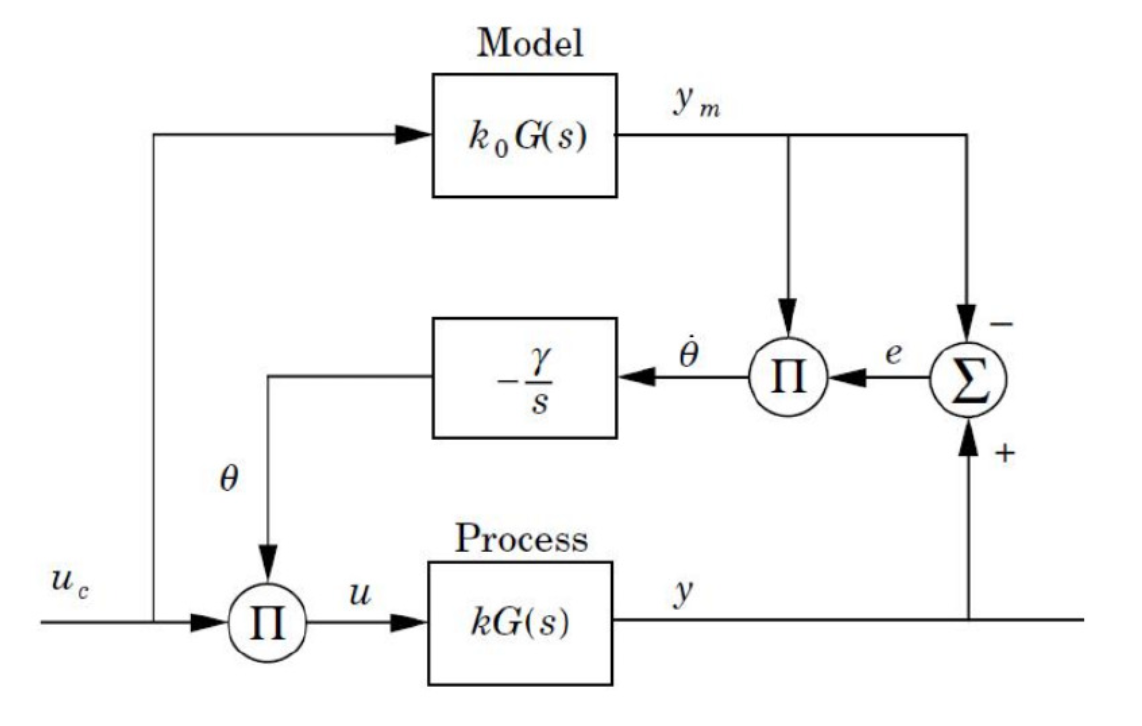

*Figure 2: Block diagram of the MRAS feedforward gain adaptation using the MIT-rule synthesis.*

**Task 1.** In order to perform the simulations to verify and experiment with the theory, you will need to build a model of the system. The Simulink library [Library_1](matlab:open('./Library_1.slx')) contains a reference generator, a set of blocks describing first order process and reference models, as well as functionalities for plotting. It may be beneficial to connect the provided goto-ports to their corresponding signals - this uses the neat signal routing functionality Simulink for plotting.

1. Implement the feedback control in Figure 1 in the Task1_MIT`.mdl` model using [Library_1](matlab:open('./Library_1.slx')) by dragging desired blocks/components.

open('Task1_MIT.mdl')

2. Run the system with $\gamma =1,\;k=1,\;k_0 =2$ to verify the implementation.

% Parameters defining the model
k = 1;
k0 = 2;
gamma = 1;
% Simulate
sim('Task1_MIT')

Provide plots of the signals involved, i.e., $u_c ,y,y_m ,e,\theta$. Can you briefly describe what happens during the simulation? Hint: Use the dataset `logsout` to plot the responses.

% Plot
HW3_plot1(logsout)

`Enter your text here.`

3. How does the rate of the adaptation change with $\gamma$? Run the simulation with different values. Provide plots and relative explanations corresponding to the tested scenarios.

- **Trial 1:**

gamma = 1; % Change this value.
sim('Task1_MIT.mdl')
HW3_plot1(logsout)

- **Trial 2:**

gamma = 1;
sim('Task1_MIT.mdl')
HW3_plot1(logsout)

- **Trial 3:**

gamma = 1;
sim('Task1_MIT.mdl')
HW3_plot1(logsout)

`Enter your text here.`

4. Does the parameter $\gamma$ change the value to which $\theta$ converges?

`Enter your text here.`

**Bonus Task:** Can you find the adjustment law with another error metric, e.g. $\left|e\left(t\right)\right|$ or $e\left(t{\left.\right)}^4 \right.$? Implement in Simulnk and investigate the same scenarios outlined in **Task 1**. 

1. Implement your feedback law:

open('Task1_Bonus')

2. Verify the implementation:

gamma = 1;
sim('Task1_Bonus')
HW3_plot1(logsout)

3. Run the simulation with different values of $\gamma$:

- **Trial 1:**

gamma = 1; 
sim('Task1_Bonus')
HW3_plot1(logsout)

- **Trial 2:**

gamma = 1;
sim('Task1_Bonus')
HW3_plot1(logsout)

- **Trial 3     **                                                     :

gamma = 1;
sim('Task1_Bonus')
HW3_plot1(logsout)

- How does the rate of the adaptation change with $\gamma$?

`Enter your text here.`

4. Does the parameter $\gamma$ change the value to which $\theta$ converges?

`Enter your text here.`

5. Comment on the differences between the current adaptation law and the one studied in **Task 1**.

`Enter your text here.`

### 1.2 The Lyapunov rule

A common alternative approach to the MIT rule is the **Lyapunov rule**. In this case, the adaptation law is given by:

$\frac{d\theta \left(t\right)}{\textrm{dt}}=-\gamma e\left(\theta ,t\right)u_c \left(t\right)$.

**Task 2.** Change the Simulink model Task2_Lyapunov to use the Lyapunov rule instead of the MIT-rule. Investigate the same scenarios outlined in **Task 1**. Provide simulation results, comment on differences between the MIT and Lyapunov rules and explain your observations.

1. Implement the Lyapunov rule in the Task2_Lyapunov model using [Library_1](matlab:open('./Library_1.slx')) by dragging desired blocks/components. 

open('Task2_Lyapunov')

2. Run the system with $\gamma =1,\;k=1,\;k_0 =2$ to verify the implementation.

gamma = 1;
sim('Task2_Lyapunov')

Provide plots of the signals involved, i.e., $u_c ,y,y_m ,e,\theta$. Can you briefly describe what happens during the simulation? Hint: Use the dataset `logsout` to plot the responses.

HW3_plot1(logsout)

`Enter your text here.`

3. How does the rate of the adaptation change with $\gamma$? Run the simulation with different values. Provide plots and relative explanations corresponding to the tested scenarios.

- **Trial 1:**

gamma = 1; 
sim('Task2_Lyapunov')
HW3_plot1(logsout)

- **Trial 2:**

gamma = 1; 
sim('Task2_Lyapunov')
HW3_plot1(logsout)

- **Trial 3:**

gamma = 1; 
sim('Task2_Lyapunov')
HW3_plot1(logsout)

`Enter your text here.`

4. Does the parameter $\gamma$ change the value to which $\theta$ converges?

`Enter your text here.`

5. Comment on differences between the MIT and Lyapunov rules, and the results obtained by using them.

`Enter your text here.`

## 2. MRAS for a first order system

Let us now consider the process being described by the model $y\left(t\right)=G\left(p\right)u\left(t\right)$, with $G\left(p\right)=\frac{b}{p+a}$ for some unknown $a,b>0$. We want to obtain a closed-loop system with behavior described by the reference model, $y_m \left(t\right)=G_m \left(p\right)u_c \left(t\right)$, with $G_m \left(p\right)=\frac{b_m }{p+a_m }$ for some known parameters $a_m ,b_m >0$. This is again a problem of model matching. Clearly, now we need to find two parameters, $\theta_1$ and $\theta_2$, to adapt both the gain and the pole location. For this purpose, we consider the controller to be given by $u\left(t\right)=\theta_1 u_c \left(t\right)-\theta_2 y\left(t\right)$, yielding the closed-loop system:

$y\left(t\right)=\frac{b\theta_1 }{p+a+b\theta_2 }u_c \left(t\right)$.

If the parameters $a$ and $b$ were known, then choosing 

$\theta_1 \left(t\right)=\frac{b_m }{b}=\theta_1^0 \;\;\;\;\;\textrm{and}\;\;\;\;\;\theta_2 \left(t\right)=\frac{a_m -a}{b}=\theta_2^0$ , 

would give $y\left(t\right)=y_m \left(t\right)$, achieving perfect model following. However, in the case of unknown parameters $a,b$ the gains $\theta_1 \left(t\right)$and $\theta_2 \left(t\right)$need to be calculated adaptively just as in the first part of the exercise. To this end, consider the error $e\left(t\right)=y\left(t\right)-y_m \left(t\right)$ and define the quadratic loss function $J\left(\theta ,t\right)=\frac{1}{2}{e\left(t\right)}^2$. The adaptation law is found by minimizing $J\left(\theta ,t\right)$ with respect to the adaptive gains. 

Using the chain rule, we obtain: $\frac{d\;J\left(\theta ,t\right)}{\textrm{dt}}=e\left(\theta ,t\right)\left(\frac{\partial e\left(\theta ,t\right)}{\partial \theta_1 \;}\frac{d\theta_1 }{\textrm{dt}}+\frac{\partial e\left(\theta ,t\right)}{\partial \theta_2 \;}\frac{d\theta_2 }{\textrm{dt}}\right)$. To have the loss function monotonically decreasing with time, we then choose $\alpha_1 ,\alpha_2 >0$ and set the adaptation law as follows:

 
$$\frac{d\theta_1 }{\textrm{dt}}=-\alpha_1 e\left(\theta ,t\right)\frac{\partial e\left(\theta ,t\right)}{\partial \theta_1 }\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\frac{d\theta_2 }{\textrm{dt}}=-\alpha_2 e\left(\theta ,t\right)\frac{\partial e\left(\theta ,t\right)}{\partial \theta_2 }$$


With the expression of the closed-loop system, the sensitivity derivatives, i.e., the partial derivatives of the error needed to compute the parameter time-derivatives are computed as:


$$\frac{\partial e\left(\theta ,t\right)}{\partial \theta_1 \left(t\right)}=\frac{b}{p+a+b\theta_2 }u_2 \left(t\right)$$



$$\frac{\partial e\left(\theta ,t\right)}{\partial \theta_2 \left(t\right)}=-\frac{b}{p+a+b\theta_2 }y\left(t\right)$$


These formulations, however, cannot be used directly because they require knowledge of both $a$ and $b$, which are unknown by the problem definition. One way around this, is to assume that the adaptive gains are close to their optimal values at all times. If this assumption is granted, then it is possible to use approximation in place of the unknown parameters:


$$\theta_2 \left(t\right)\approx \frac{a_m -a}{b}\Leftrightarrow a+b\theta_2 \left(t\right)\approx a_m$$


which implies

$\frac{\partial e\left(\theta ,t\right)}{\partial \theta_1 \left(t\right)}\approx \frac{b}{p+a_m }u_c \left(t\right)\;\;\;\;\;\;\;\;\;\;\frac{\partial e\left(\theta ,t\right)}{\partial \theta_2 \left(t\right)}\approx \frac{b}{p+a_m }y\left(t\right)$.

### 2.2. The MIT-rule

Since $b$ is unknown but positive and constant, we simply define the adaptive gains as $\gamma_i =a_i a_m /b$. The complete MRAS is then given by the feedback controller $u\left(t\right)=\theta_1 u_c \left(t\right)-\theta_2 y\left(t\right)$, where the parameters are updated by the adaptation rules obtained when using the parameter approximations in the sensitivity derivatives, yielding:

$\frac{d\theta_1 }{\textrm{dt}}=-\gamma_1 \frac{a_m }{p+a_m }e\left(t\right)u_c \left(t\right)\;\;\;\;\;\;\;\;\;\;\;\;\frac{d\theta_2 }{\textrm{dt}}=\gamma_2 \frac{a_m }{p+a_m }e\left(t\right)y\left(t\right)$.

Note that the approximation may be crude if starting far away from the true parameter values $\theta_i^0 \;$.

**Task 3.** Similar to the previous exercise, we need to build a model of the system in Simulink. The Simulink library [Library_2](matlab:open('./Library_2.slx')) contains a reference generator, a set of blocks describing first order (SISO) process and reference models, as well as functionalities for plotting.

1. Implement the feedback loop in the Task3_MIT model using [Library_2](matlab:open('./Library_2.slx')) by dragging desired blocks/components. 

open('Task3_MIT')

2. Run with $\gamma =1,a=1,b=0\ldotp 5,a_m =b_m =2$ to verify the implementation. Plot the signals involved. Can you briefly describe what happens during the simulation?

% Parameters defining the model
a     = 1;
b     = 0.5;
am    = 2;
bm    = 2;
gamma = 1;
% Simulate
sim('Task3_MIT')
% Plot
HW3_plot2(logsout)

`Enter your text here.`

3. How does the rate of the adaptation change with $\gamma$? Run the simulation with different values. Provide plots and relative explanations corresponding to the tested scenarios.

- **Trial 1:**

gamma = 1; 
sim('Task3_MIT')
HW3_plot2(logsout)

- **Trial 2:**

gamma = 1; 
sim('Task3_MIT')
HW3_plot2(logsout)

- **Trial 3:**

gamma = 1; 
sim('Task3_MIT')
HW3_plot2(logsout)

`Enter your text here.`

4. Do the parameters $a$ and $b$ affect the rate of adaptation?

- **Trial 1:**

a     = 1; 
b     = 0.5; 
gamma = 1; 
sim('Task3_MIT')
HW3_plot2(logsout)

- **Trial 2:**

a     = 1; 
b     = 0.5; 
sim('Task3_MIT')
HW3_plot2(logsout)

- **Trial 3:**

a     = 1; 
b     = 0.5; 
sim('Task3_MIT')
HW3_plot2(logsout)

`Enter your text here.`

5. What happens when you alter the reference model? Try out a few simulations and provide results.

- **Trial 1:**

a     = 1; 
b     = 0.5; 
am    = 2;
bm    = 2;
sim('Task3_MIT')
HW3_plot2(logsout)

- **Trial 2:**

am    = 2;
bm    = 2;
sim('Task3_MIT')
HW3_plot2(logsout)

- **Trial 3:**

am    = 2;
bm    = 2;
sim('Task3_MIT')
HW3_plot2(logsout)

`Enter your text here.`

6. Examine the parameter plane plot, with $\theta_2$ as a function of $\theta_1$. To which values do the parameters converge? Is this expected from the theory?

% Parameters defining the model
a     = 1; 
b     = 0.5; 
am    = 2;
bm    = 2;
gamma = 1; 
% Simulate
sim('Task3_MIT')
% Plot
HW3_plot2(logsout)

`Enter your text here.`

### 2.3 The Lyapunov Rule

Let us now use conventional Lyapunov theory. To this end, we write the error dynamics:

$\frac{d\;e\left(t\right)}{\textrm{dt}}=-a_m e\left(t\right)-\left(b\theta_2 \left(t\right)+a-a_m \right)y\left(t\right)+\left(b\theta_1 -b_m \right)u_c \left(t\right)$.

The objective is to construct a parameter adjustment mechanism such that the error $y\left(t\right)-y_m \left(t\right)$ is driven to zero. This is achieved when the adaptive parameters approach the values which can guarantee perfect model following. Introduce the following Lyapunov function, dropping time dependance for notational convenience:


$$V\left(e,\theta \right)=\frac{1}{2}\left(e^2 +\frac{1}{b\gamma \;}{\left(b\theta_2 \left(t\right)+a-a_m \right)}^2 +\frac{1}{b\gamma }\left(b\theta_1 -b_m {\left.\right)}^2 \right)\right.$$


Applying the chain rule, the time derivative of the Lyapunov function is obtained:


$$\frac{d\;V}{\textrm{dt}}=-\alpha_m e^2 +\frac{1}{\gamma \;}\left(b\theta_2 \left(t\right)+\alpha -\alpha_m \;\right)\left(\frac{d\theta_2 }{\textrm{dt}}-\gamma \textrm{ye}\right)+\frac{1}{\gamma \;}\left(b\theta_1 -b_m \right)\left(\frac{d\theta_1 }{\textrm{dt}}+\gamma u_c e\;\right)$$


This function is zero when $e\left(t\right)=0$ and the parameters assuming the correct value for model for perfect model following. The time derivative is: 


$$\frac{d\;V}{\textrm{dt}}=-a_{m\;} e^2 +\frac{1}{\gamma \;}\;\left(b\;\theta_{2\;} +a-a_m \right)\cdot \left(\frac{{d\;\theta }_2 }{\textrm{dt}}-\gamma \;y\;e\right)+\frac{1}{\gamma \;}\left(b\theta_1 -b_m \right)\cdot \left(\frac{{d\theta }_1 }{\textrm{dt}}+\gamma \;u_c \;e\right)$$


If the parameters are updated as


$$\frac{d\theta_1 \left(t\right)}{\textrm{dt}}=-\gamma u_c \left(t\right)e\left(t\right)\;\;\;\;\;\;\;\;\;\;\;\;\frac{d\theta_2 \left(t\right)}{\textrm{dt}}=\gamma y\left(t\right)e\left(t\right)$$


we get a derivative of the Lyapunov function which is negative semidefinite, i.e., $\frac{d\;V}{\textrm{dt}}=-a_m {e\left(t\right)}^2 \le 0$, implying that $e\left(t\right)\to 0\ldotp$

**Task 4.** Similarly to the previous exercise, we investigate the system in Simulink.

1. Implement the feedback loop in the Task4_Lyapunov model using [Library_2](matlab:open('./Library_2.slx')) by dragging desired blocks/components. 

open('Task4_Lyapunov')

2. Run with $\gamma =1,a=1,b=0\ldotp 5,a_m =b_m =2$ to verify the implementation. Plot the signals involved. Can you briefly describe what happens during the simulation?

sim('Task4_Lyapunov')
HW3_plot2(logsout)

`Enter your text here.`

3. How does this feedback law based on Lyapunov theory differ from that of the MIT-rule? Explain. Try out a few simulations and provide results.

- **Trial 1:**

a     = 1; 
b     = 0.5; 
am    = 2; 
bm    = 2; 
gamma = 1; 
sim('Task4_Lyapunov')
HW3_plot2(logsout)

- **Trial 2:**

a     = 1; 
b     = 0.5; 
am    = 2; 
bm    = 2; 
gamma = 1; 
sim('Task4_Lyapunov')
HW3_plot2(logsout)

- **Trial 3:**

a     = 1; 
b     = 0.5; 
am    = 2; 
bm    = 2; 
gamma = 1; 
sim('Task4_Lyapunov')
HW3_plot2(logsout)

- **Trial 4:**

a     = 1; 
b     = 0.5; 
am    = 2; 
bm    = 2; 
gamma = 1; 
sim('Task4_Lyapunov')
HW3_plot2(logsout)

- **Trial 5:**

a     = 1; 
b     = 0.5; 
am    = 2; 
bm    = 2; 
gamma = 1; 
sim('Task4_Lyapunov')
HW3_plot2(logsout)

- **Trial 6:**

a     = 1; 
b     = 0.5; 
am    = 2; 
bm    = 2; 
gamma = 1; 
sim('Task4_Lyapunov')
HW3_plot2(logsout)

`Enter your text here.`

4. Which would you implement in practice? Which guarantees stability?

`Enter your text here.`

## 3. Quadrotor Control Using Model Reference Adaptive Control

In the previous examples, we learned about MRAS to closely match the system and the reference model outputs. In this example we will learn how to control a quadrotor with unknown dynamics and external disturbances using model reference adaptive control (MRAC) to track an ideal reference model.The six degree-of-freedom (DOF) quadrotor dynamics are modeled in Simulink® and Simscape, the MRAC controller is implemented using the [Model Reference Adaptive Control](docid:slcontrol_ug#mw_dc1ded56-88ad-43a4-8388-3ef90d2e24b1) block.

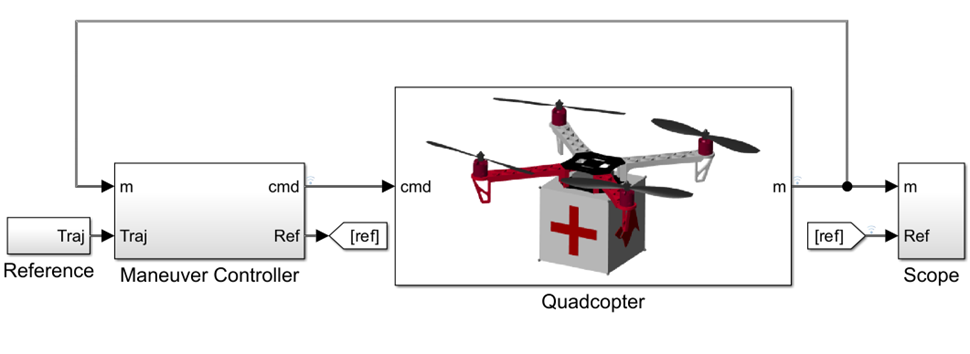

The goal of this example is to control the quadrotor to follow a trajectory defined by waypoints in the presence of uncertainties in both the model and external disturbances. 

This example uses Curve Fitting Toolbox™ for waypoint trajectory planning.

### Quadrotor Model

A quadrotor is agile but unstable due to its nonlinear model and actuator uncertainties. Designing or tuning controllers is challenging, and fixed-gain controllers lack robustness. An adaptive MRAC controller is ideal for managing these issues.

The 6-DOF quadrotor dynamics are defined in Euler angles as follows.

#### **Outer Guidance Loop**


$$\ddot{\zeta} =-G+\frac{1}{M}R_t F$$


#### **Inner Attitude Loop**


$$\ddot{\xi} =-R_r^{-1} J^{-1} \left(R_r \dot{\xi} +JR_r \dot{\xi} \right)-R_r^{-1} \left(\frac{\partial R_r }{\partial \;\theta }\dot{\theta} +\frac{\partial R_r }{\partial \;\psi }\dot{\psi} \right)\dot{\xi} +R_r^{-1} J^{-1} T\;$$


Here:

- The state vector $\zeta ={\left\lbrack x,y,z\right\rbrack }^T ,\xi ={\left\lbrack \phi \;,\theta ,\psi \right\rbrack }^T$ contains positions and attitude angles in the inertial frame of reference.

- $V={\left\lbrack u,v,w\right\rbrack }^T ,\Omega ={\left\lbrack p,q,r\right\rbrack }^T \;$contains the translation velocity and angular rotation rates in the body fixed frame.

- $G=\left\lbrack 0,0,g\right\rbrack$ is the gravity vector

- $F$ is the control input for the outer guidance loop.

- $T$ is the control input for the inner attitude loop.

The rotation matrices for translation and rotation are $R_t$ and $R_r$, respectively.


$$R_t =\left\lbrack \begin{array}{ccc}
C_{\theta \;} C_{\psi \;}  & {-C}_{\theta \;} S_{\psi \;}  & S_{\theta } \\
S_{\phi \;} S_{\theta \;} C_{\psi } +C_{\phi \;} S_{\psi }  & {-S}_{\phi \;} S_{\theta \;} S_{\psi } +C_{\phi \;} C_{\psi }  & {-S}_{\phi \;} C_{\theta \;} \\
{-C}_{\phi \;} S_{\theta \;} C_{\psi } +S_{\phi \;} S_{\psi }  & C_{\phi \;} S_{\theta \;} S_{\psi } +S_{\phi \;} C_{\psi }  & C_{\phi \;} C_{\theta \;} 
\end{array}\right\rbrack$$



$$R_r =\left\lbrack \begin{array}{ccc}
C_{\psi \;} C_{\theta \;}  & S_{\psi \;}  & 0\\
{-S}_{\phi \;} C_{\theta \;}  & C_{\psi }  & 0\\
S_{\theta \;}  & 0 & 1
\end{array}\right\rbrack$$


Here, the $C$ and $S$ elements are the cosine and sine of their respective attitude angles.

Open the quadrotor control project and model.

open("MRACQuadrotorControlExample/Quadcopter_Drone.prj")
mdl = "quadcopter_package_delivery";

### MRAC for Quadrotor Control and Navigation

The quadrotor vehicle has outer and inner layers for control. The outer-loop dynamics affect the position of the vehicle in $X$, $Y$, and $Z$ spatial directions and the outer-loop control is used for guidance and navigation. The inner loop is the attitude loop, which affects the vehicle body roll, pitch and yaw angles. The inner-loop control tracks desired reference angles derived from the outer loop.

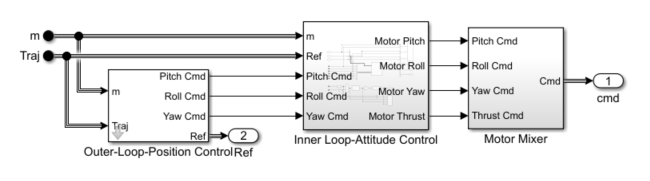

#### Outer-Loop Control

The baseline outer-loop controller, which is responsible for vehicle position control, is evaluated using the dynamics inversion method. The linear feedback representation of the outer-loop system dynamics are:


$$\ddot{\zeta} =w$$


The pseudo-control $w$ is computed using a PID controller.


$$w=-\left(K_p e+K_d \dot{\;e} +K_i \int e\textrm{dt}\right)$$


Denoting the term $U=\left\lbrack u_1 ,u_2 ,u_3 \right\rbrack =R_{t\;} F$, you can define the desired controller as $U=\textrm{Mw}+\textrm{MG}$. Therefore, $|F|=|U|$ is the total thrust for steady hovering.

The reference command for the desired roll and pitch attitude can be derived as follows.


$$\phi_d =-\textrm{sgn}\left(u_2 \right)\cos^{-1} \left(\sqrt{\frac{u_3^2 }{u_2^2 +u_3^2 }}\right)$$



$$\theta_d =-\textrm{sgn}\left(u_1 \right)\cos^{-1} \left(\sqrt{\frac{u_2^2 +u_3^2 }{{u_1^{2\;} +u}_2^2 +u_3^2 }}\right)$$


Since trajectory tracking is independent of the yaw orientation of the vehicle, the desired yaw angle is given by the user through a stick command.

#### Inner-Loop Control

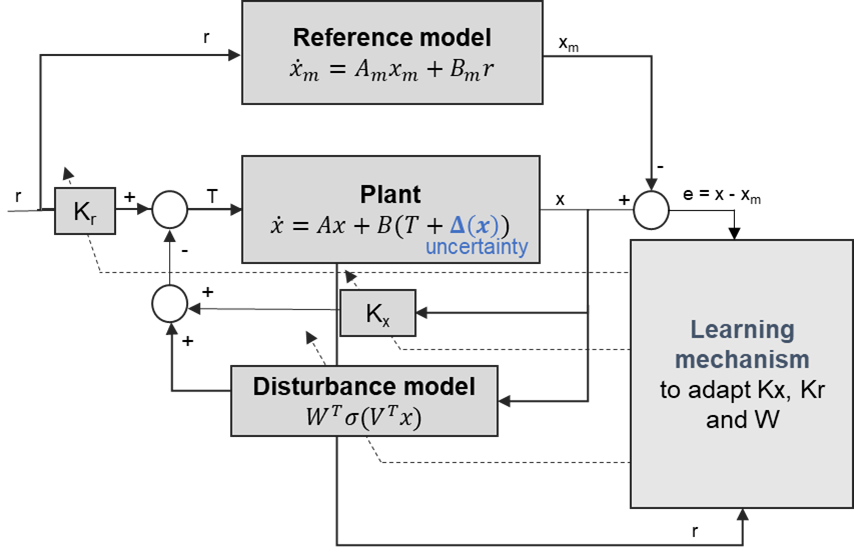

The inner-loop control assumes no knowledge of the model and therefore uses MRAC to achieve trajectory tracking despite model uncertainty and external disturbances. The inner loop control assumes a linear nominal model with the following form.


$$\ddot{\xi} =A\xi +\textrm{BT}$$


Here, $\xi \;$contains the inner-loop states and $T$ contains the roll, pitch, and yaw input torques.

The total unmodeled dynamics and external uncertainties are considered to be one lumped term $\Delta \;\left(\zeta ,\xi \;\right)$. Express the nominal model in control affine form as follows.


$$\ddot{\xi} =A\xi +B\left(\Delta \;\left(\zeta ,\xi \;\right)+T\right)$$


Using MRAC, you can define the total controller torque $T$ as follows.


$$T=-k_{\xi \;} \xi +k_r r-\hat{\;\Delta }$$


Here, $k_{\xi }$ and $k_r$ are the feedback and feedforward controller gains and $\hat{\;\Delta \;}$is the MRAC estimate of the total uncertainty.

The closed-loop nominal system with the MRAC controller is:


$$\ddot{\xi} =A\xi +B\left(-k_{\xi \;} \xi +k_r r-\hat{\;\Delta } +\Delta \;\left(\zeta ,\xi \;\right)\right)$$



$$\ddot{\xi} =\left(A-k_{\xi \;} \right)\xi +Bk_r r+B\left(\Delta \;\left(\zeta ,\xi \;\right)-\hat{\;\Delta } \right)$$


The gains $k_{\xi \;}$and $k_r$ are updated to acheive model matching condition as follows.

$\left(A-k_{\xi \;} \right)=A_m$ and $Bk_r =B_m$

And $\hat{\;\Delta \;}$ is learned to approximate the total uncertainty. For more information on the update equations for feedback gains, feedforward gains, and uncertainty approximation, see [Model Reference Adaptive Control](docid:slcontrol_ug#mw_a2ef6ba4-fefc-479a-ba69-bb5397cf3340) .

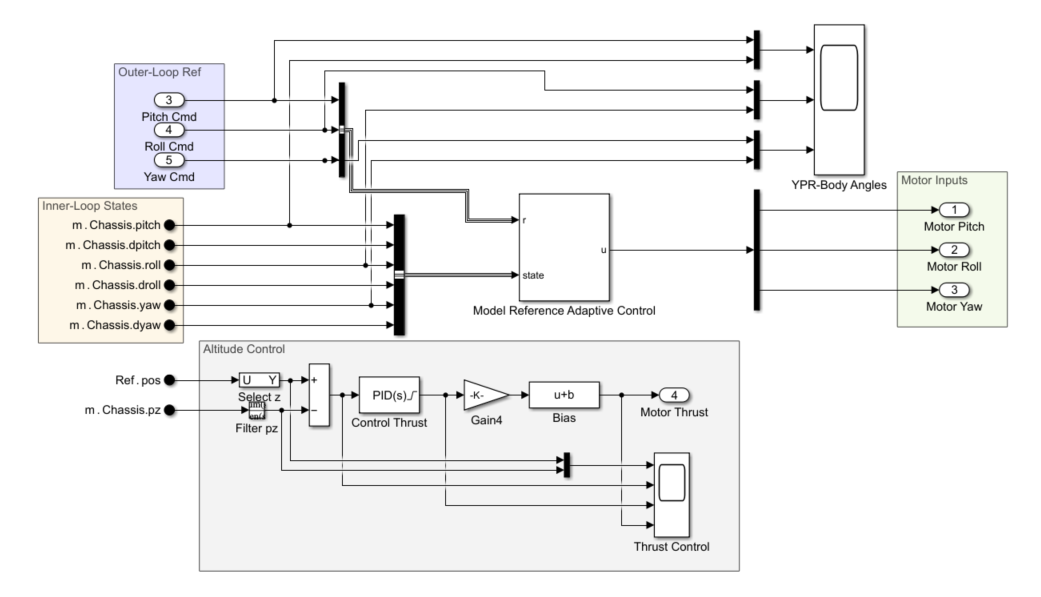

### Nominal Model and Reference Model Parameters

The nominal and reference models of the MRAC are defined as follows. The desired second-order response is defined by selecting the natural frequency `wn` and damping coefficient `d`.

% Nominal Model
A = [0 1 0 0 0 0;
     1 1 0 0 0 0;
     0 0 0 1 0 0;
     0 0 1 1 0 0;
     0 0 0 0 0 1;
     0 0 0 0 1 1];
B = [0 0 0;
     1 0 0;
     0 0 0;
     0 1 0;
     0 0 0;
     0 0 1];

% Reference Model
wn = 4;
d = 0.6;
Am = [   0       1     0       0     0       0;
     -wn^2 -2*d*wn     0       0     0       0;
         0       0     0       1     0       0;
         0       0 -wn^2 -2*d*wn     0       0;
         0       0     0       0     0       1;
         0       0     0       0 -wn^2 -2*d*wn];
Bm = [   0    0    0;
      wn^2    0    0;
         0    0    0;
         0 wn^2    0;
         0    0    0;
         0    0 wn^2];

### Controller Parameters

The MRAC controller contains three control elements: feedback, feedforward, and adaptive control.

kx = 0; % Initial feedback gain
kr = 0; % Initial feedforward gain

In this example, the Model Reference Adaptive Controller block is configured to adjust the feedback and feedforward gains online.

gamma_k = 100; % Learning rate for gain adaptation.

The adaptive control estimates and cancels model uncertainties online. For this example, the controller is configured to use a single hidden layer (SHL) neural network to estimate the uncertainties. The SHL network has two layers for adapting the controller model.

gamma_w = 5; % Outer-layer learning rate.
gamma_v = 1; % Inner-layer learning rate for updating the weights of the SHL network.
N = 25; % Number SHL hidden neurons.
Q_mrac = [100 175 100 175 100 125]; % Lyapunov coefficient for the controller weight updates.

### Simulate Model

The quadrotor reference trajectory is designed using waypoint guidance markers. Midway through the flight, the vehicle performs a yaw maneuver. Finally, before final waypoint, the vehicle payload is jettisoned to simulate sudden payload change, which introduces uncertainty in the vehicle mass.

sim(mdl)

**Task 5**. Change the initial feedback gain and feedforward gain to produce a better tracking performance. What do you observe?

`Enter your text here.`